% Generate samples using Gaussian
mu = 4;
sigma = 3;
samples = normrnd(mu,sigma,[150,1]);

% Attemp to recover parameters
m = length(samples)

m = 150

theta_1 = (1/m)*sum(samples);
theta_2 = (1/m)*sum((samples' - repmat(theta_1,1,m)).^2);
mu_hat = theta_1

mu_hat = 4.0965

sigma_hat = sqrt(theta_2)

sigma_hat = 3.0058

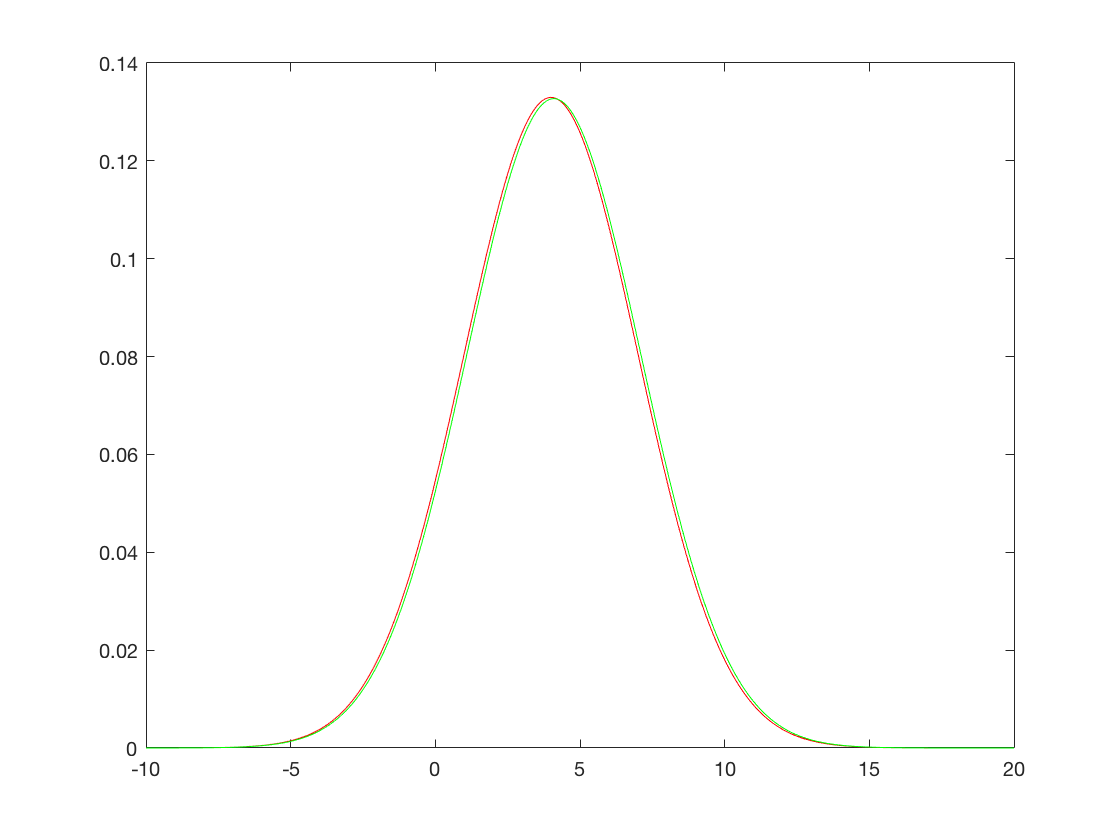


%Plot results
x = [-10:.1:20];
figure;
clf;
plot(x,normpdf(x,mu,sigma),'Color','red');
hold on;
plot(x,normpdf(x,mu_hat,sigma_hat),'Color','green');
hold off;